# Question - 1

clc;

a = [1:8; 9:16; 17:24; 25:32; 33:40]

a =      1     2     3     4     5     6     7     8
     9    10    11    12    13    14    15    16
    17    18    19    20    21    22    23    24
    25    26    27    28    29    30    31    32
    33    34    35    36    37    38    39    40


## (a)

b = a([1 3 5], [1 2 4 8]);
b

b =      1     2     4     8
    17    18    20    24
    33    34    36    40


## (b)

c = [a(5, :), reshape(a(:, 4), 1, []), reshape(a(:, 6), 1, [])]

c =     33    34    35    36    37    38    39    40     4    12    20    28    36     6    14    22    30    38


# Question - 2

clc;

a = 0.75;
b = 11.3;

x = [2, 5, 1, 9];
y = [0.2, 1.1, 1.8, 2];
z = [-3, 2, 5, 4];

A1 = ((x.^1.1 .* y.^-2 .* z.^5) / (a + b).^(b / 3)) + a .* (((z / x) + (y / 2)) / z.^a)

A1 =   -0.8522 - 0.0225i   0.2649 - 0.0225i   0.3335 - 0.0225i   0.4951 - 0.0225i


# Question - 3

clc;

syms x1 x2 x3 x4;

eqn1 = 2*x1 + x2 + x3 - x4 == 12;
eqn2 = x1 + 5*x2 - 5*x3 + 6*x4 == 35;
eqn3 = - 7*x1 + 3*x2 - 7*x3 - 5*x4 == 7;
eqn4 = x1 - 5*x2 + 2*x3 + 7*x4 == 21;

[A, B] = equationsToMatrix([eqn1, eqn2, eqn3, eqn4], [x1, x2, x3, x4]);
X = vpa(linsolve(A, B), 6)

$$X = \left(\begin{array}{c} 35.278\\ -28.2511\\ -40.852\\ -10.5471 \end{array}\right)$$

# Question - 3

## On the same plot

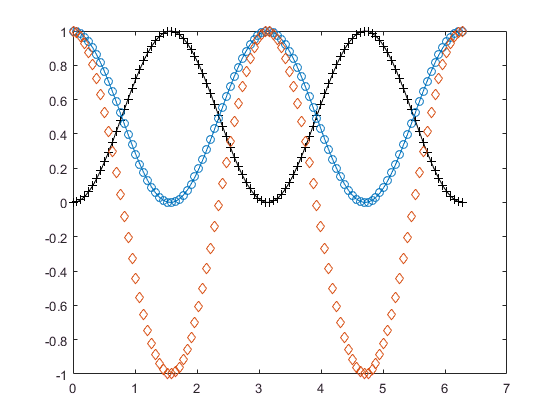

clc;
close all;
x = linspace(0, 2*pi);
y = sin(x).^2;

plot(x, y, '-+k')
hold on

y2 = cos(x).^2;
plot(x, y2, '-o')
hold on

y3 = cos(2*x);
plot(x, y3, 'd')
hold off

## On Subplot

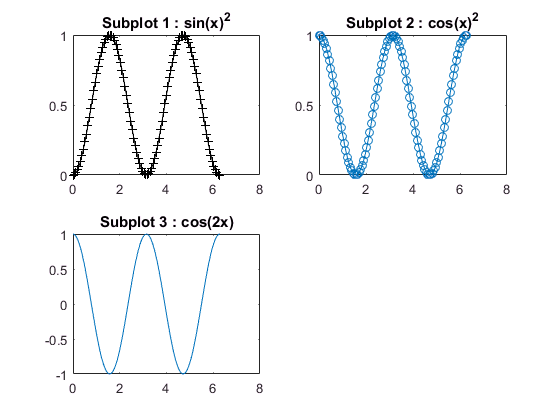

clc;
close all;
subplot(2, 2, 1);

x = linspace(0, 2*pi);
y1 = sin(x).^2;

plot(x, y1, '-+k')
title('Subplot 1 : sin(x)^2')

subplot(2, 2, 2)

y2 = cos(x).^2;
plot(x, y2, '-o')
title('Subplot 2 : cos(x)^2')

subplot(2, 2, 3)

y3 = cos(2*x);
plot(x, y3, '-')
title('Subplot 3 : cos(2x)')

# Question - 5

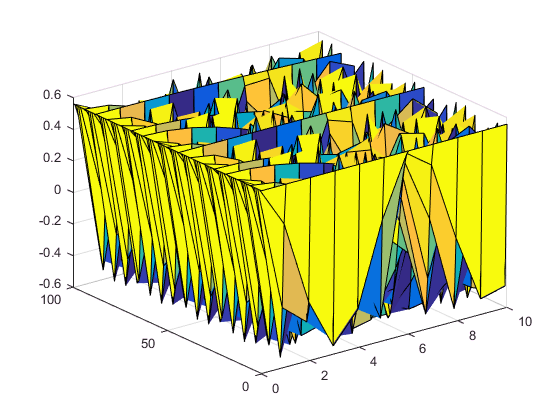

clc;
close all;

[x, y] = meshgrid(0:10, 0:100);

z = 0.56 .* cos(x .* y);

surf(x, y, z)

# Question - 6

help findGrad


No help found for findGrad.m.



## (a)

clc;

findGrad(1, 1)

ans = 0

## (b)

findGrad(1, -2)

ans = 0

# Question - 7

## (a)

clc;

syms x;

eqn = x^7 - 8*x^5 + 7*x^4 + 5*x^3 - 8*x + 9;

coeff = coeffs(eqn, 'All');

sol = vpa(roots(coeff), 4)

$$sol = \left(\begin{array}{c} -3.136\\ -0.8007+0.6944\,\mathrm{i}\\ -0.8007-0.6944\,\mathrm{i}\\ 0.6139+0.6513\,\mathrm{i}\\ 0.6139-0.6513\,\mathrm{i}\\ 1.755+0.3308\,\mathrm{i}\\ 1.755-0.3308\,\mathrm{i} \end{array}\right)$$

## (b)

clc;

syms x(t);

Dx = diff(x);

ode = diff(x,t,2) + 10 * diff(x,t) + 5 * x == 11;

cond1 = x(0) == 1;
cond2 = Dx(0) == -1;
conds = [cond1 cond2];

xSol(t) = dsolve(ode,conds);
xSol = vpa(simplify(xSol), 4)

$$xSol(t) = 0.1826\,{\mathrm{e}}^{-9.472\,t}-1.383\,{\mathrm{e}}^{-0.5279\,t}+2.2$$

## (c)

clc;
syms x;

f = x^5 - 8.*x^4 + 5.*x^3 - 7.*x^2 + 11.*x -9;

f1 = diff(f, x)

$$f1 = 5\,x^{4}-32\,x^{3}+15\,x^{2}-14\,x+11$$

f2 = diff(f, x, 2)

$$f2 = 20\,x^{3}-96\,x^{2}+30\,x-14$$

## (d)

clc;
syms x

ll = 0;
ul = 5;
f = 1 / (0.8.*x^2 + 0.5.*x + 2);

result = vpa(int(f, ll, ul),4)

$$result = 0.8774$$

# Question - 8

## (a)

clc;
close all;

year = 1930:10:2020;
pop = [249 277 316 350 431 539 689 833 1014 1203];

pol = polyfit(year, pop, 2);

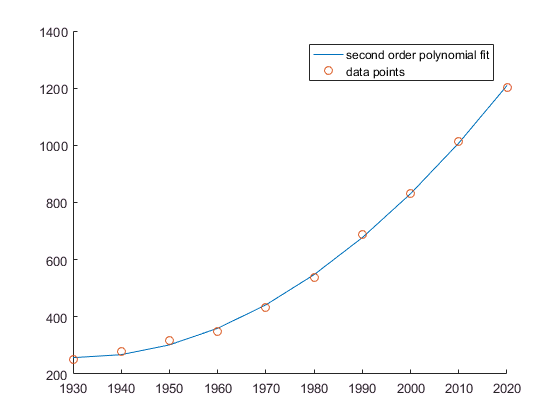


f = polyval(pol, year);
hold on
plot(year, f)
hold on
plot(year, pop, 'o')
legend('second order polynomial fit', 'data points') 
hold off

## (b)

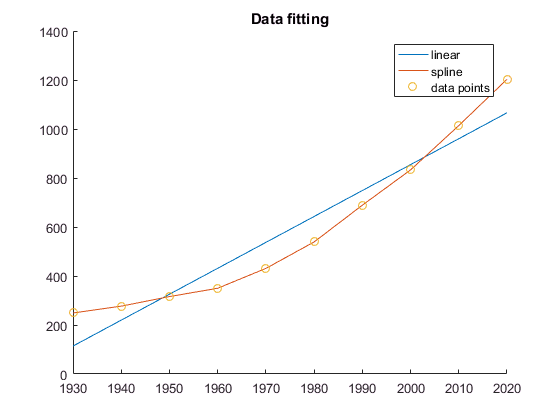

clc;
close all;

year = 1930:10:2020;
pop = [249 277 316 350 431 539 689 833 1014 1203];
predict_year = 1995;

linear_int = polyfit(year, pop, 1);
sp_int = spline(year, pop, year);
f = polyval(linear_int,year);

Linear = interp1(year, pop, predict_year);
Spline = spline(year, pop, predict_year);
resutl = table(Linear, Spline);

hold on
plot(year, f)
hold on
plot(year, sp_int, year, pop, 'o')
title('Data fitting')
legend('linear', 'spline', 'data points') 
hold off